# Introduccio al Matlab

## Operacio amb vectors

% Creació de vectors
x = [1 2 3 4 5] % vector fila

x =      1     2     3     4     5


y = [5; 6; 7; 8; 9] % vector columna

y =      5
     6
     7
     8
     9


x = x' % transposada

x =      1
     2
     3
     4
     5


z = 1:2:10 % progresió

z =      1     3     5     7     9


q = zeros([1 5])

q =      0     0     0     0     0


k = ones([5 1])

k =      1
     1
     1
     1
     1


x'*y % producte escalar

ans = 115

norm(x) % longitud

ans = 7.4162

sqrt(x'*x)

ans = 7.4162

q = rand([10000000 1]);
tic
q'*q

ans = 3.3333e+06

toc

Elapsed time is 0.006899 seconds.


## Operacions amb matrius

X = rand([10 10]) %rand 10x10

X =     0.3709    0.7791    0.3241    0.5022    0.1325    0.0526    0.5307    0.5079    0.2352    0.7374
    0.8812    0.2050    0.3160    0.3959    0.3989    0.5021    0.7515    0.0530    0.5069    0.3936
    0.5263    0.5253    0.7530    0.2875    0.5259    0.7767    0.1403    0.5185    0.1887    0.0190
    0.0831    0.0181    0.1778    0.5803    0.2312    0.9745    0.5694    0.6513    0.7327    0.7389
    0.3540    0.0994    0.0337    0.4223    0.5707    0.9664    0.9421    0.6208    0.8170    0.4986
    0.8093    0.2691    0.2595    0.6816    0.3173    0.3478    0.2569    0.9776    0.6613    0.9193
    0.7064    0.0552    0.4214    0.9351    0.2923    0.5836    0.4076    0.0153    0.9059    0.1297
    0.0949    0.9586    0.8267    0.5069    0.9962    0.9824    0.1887    0.3448    0.2022    0.4412
    0.2348    0.6785    0.2238    0.6644    0.3205    0.2822    0.2488    0.8461    0.4985    0.3620
    0.1457    0.6168    0.3856    0.0564    0.0259    0.2352    0.6950    0.6959    0.0

s = size(X) % mides de cada dimensio

s =     10    10


files = s(1); columnes = s(2);
ndims(X) %dimensions

ans = 2

Z = [X X]

Z =     0.3709    0.7791    0.3241    0.5022    0.1325    0.0526    0.5307    0.5079    0.2352    0.7374    0.3709    0.7791    0.3241    0.5022    0.1325    0.0526    0.5307    0.5079    0.2352    0.7374
    0.8812    0.2050    0.3160    0.3959    0.3989    0.5021    0.7515    0.0530    0.5069    0.3936    0.8812    0.2050    0.3160    0.3959    0.3989    0.5021    0.7515    0.0530    0.5069    0.3936
    0.5263    0.5253    0.7530    0.2875    0.5259    0.7767    0.1403    0.5185    0.1887    0.0190    0.5263    0.5253    0.7530    0.2875    0.5259    0.7767    0.1403    0.5185    0.1887    0.0190
    0.0831    0.0181    0.1778    0.5803    0.2312    0.9745    0.5694    0.6513    0.7327    0.7389    0.0831    0.0181    0.1778    0.5803    0.2312    0.9745    0.5694    0.6513    0.7327    0.7389
    0.3540    0.0994    0.0337    0.4223    0.5707    0.9664    0.9421    0.6208    0.8170    0.4986    0.3540    0.0994    0.0337    0.4223    0.5707    0.9664    0.9421    0.6208    0.8170  

Z = [X;X]

Z =     0.3709    0.7791    0.3241    0.5022    0.1325    0.0526    0.5307    0.5079    0.2352    0.7374
    0.8812    0.2050    0.3160    0.3959    0.3989    0.5021    0.7515    0.0530    0.5069    0.3936
    0.5263    0.5253    0.7530    0.2875    0.5259    0.7767    0.1403    0.5185    0.1887    0.0190
    0.0831    0.0181    0.1778    0.5803    0.2312    0.9745    0.5694    0.6513    0.7327    0.7389
    0.3540    0.0994    0.0337    0.4223    0.5707    0.9664    0.9421    0.6208    0.8170    0.4986
    0.8093    0.2691    0.2595    0.6816    0.3173    0.3478    0.2569    0.9776    0.6613    0.9193
    0.7064    0.0552    0.4214    0.9351    0.2923    0.5836    0.4076    0.0153    0.9059    0.1297
    0.0949    0.9586    0.8267    0.5069    0.9962    0.9824    0.1887    0.3448    0.2022    0.4412
    0.2348    0.6785    0.2238    0.6644    0.3205    0.2822    0.2488    0.8461    0.4985    0.3620
    0.1457    0.6168    0.3856    0.0564    0.0259    0.2352    0.6950    0.6959    0.0

Z = [X X; X X]

Z =     0.3709    0.7791    0.3241    0.5022    0.1325    0.0526    0.5307    0.5079    0.2352    0.7374    0.3709    0.7791    0.3241    0.5022    0.1325    0.0526    0.5307    0.5079    0.2352    0.7374
    0.8812    0.2050    0.3160    0.3959    0.3989    0.5021    0.7515    0.0530    0.5069    0.3936    0.8812    0.2050    0.3160    0.3959    0.3989    0.5021    0.7515    0.0530    0.5069    0.3936
    0.5263    0.5253    0.7530    0.2875    0.5259    0.7767    0.1403    0.5185    0.1887    0.0190    0.5263    0.5253    0.7530    0.2875    0.5259    0.7767    0.1403    0.5185    0.1887    0.0190
    0.0831    0.0181    0.1778    0.5803    0.2312    0.9745    0.5694    0.6513    0.7327    0.7389    0.0831    0.0181    0.1778    0.5803    0.2312    0.9745    0.5694    0.6513    0.7327    0.7389
    0.3540    0.0994    0.0337    0.4223    0.5707    0.9664    0.9421    0.6208    0.8170    0.4986    0.3540    0.0994    0.0337    0.4223    0.5707    0.9664    0.9421    0.6208    0.8170  

Z(1, 1) = 0

Z =          0    0.7791    0.3241    0.5022    0.1325    0.0526    0.5307    0.5079    0.2352    0.7374    0.3709    0.7791    0.3241    0.5022    0.1325    0.0526    0.5307    0.5079    0.2352    0.7374
    0.8812    0.2050    0.3160    0.3959    0.3989    0.5021    0.7515    0.0530    0.5069    0.3936    0.8812    0.2050    0.3160    0.3959    0.3989    0.5021    0.7515    0.0530    0.5069    0.3936
    0.5263    0.5253    0.7530    0.2875    0.5259    0.7767    0.1403    0.5185    0.1887    0.0190    0.5263    0.5253    0.7530    0.2875    0.5259    0.7767    0.1403    0.5185    0.1887    0.0190
    0.0831    0.0181    0.1778    0.5803    0.2312    0.9745    0.5694    0.6513    0.7327    0.7389    0.0831    0.0181    0.1778    0.5803    0.2312    0.9745    0.5694    0.6513    0.7327    0.7389
    0.3540    0.0994    0.0337    0.4223    0.5707    0.9664    0.9421    0.6208    0.8170    0.4986    0.3540    0.0994    0.0337    0.4223    0.5707    0.9664    0.9421    0.6208    0.8170  

v = Z(:) % ho afaga tot i ho posa en COLUMNA

v =          0
    0.8812
    0.5263
    0.0831
    0.3540
    0.8093
    0.7064
    0.0949
    0.2348
    0.1457


v = Z(:)' % ho afaga tot i ho posa en FILA

v =          0    0.8812    0.5263    0.0831    0.3540    0.8093    0.7064    0.0949    0.2348    0.1457    0.3709    0.8812    0.5263    0.0831    0.3540    0.8093    0.7064    0.0949    0.2348    0.1457    0.7791    0.2050    0.5253    0.0181    0.0994    0.2691    0.0552    0.9586    0.6785    0.6168    0.7791    0.2050    0.5253    0.0181    0.0994    0.2691    0.0552    0.9586    0.6785    0.6168    0.3241    0.3160    0.7530    0.1778    0.0337    0.2595    0.4214    0.8267    0.2238    0.3856



%escombrar i substituir
Z(Z < 0.5) = 0 % posa tots els valors < 0.5 a 0

Z =          0    0.7791         0    0.5022         0         0    0.5307    0.5079         0    0.7374         0    0.7791         0    0.5022         0         0    0.5307    0.5079         0    0.7374
    0.8812         0         0         0         0    0.5021    0.7515         0    0.5069         0    0.8812         0         0         0         0    0.5021    0.7515         0    0.5069         0
    0.5263    0.5253    0.7530         0    0.5259    0.7767         0    0.5185         0         0    0.5263    0.5253    0.7530         0    0.5259    0.7767         0    0.5185         0         0
         0         0         0    0.5803         0    0.9745    0.5694    0.6513    0.7327    0.7389         0         0         0    0.5803         0    0.9745    0.5694    0.6513    0.7327    0.7389
         0         0         0         0    0.5707    0.9664    0.9421    0.6208    0.8170         0         0         0         0         0    0.5707    0.9664    0.9421    0.6208    0.8170  

Z(Z ~= 0) = 1 % posa tots els valors diferents a 0 a 1

Z =      0     1     0     1     0     0     1     1     0     1     0     1     0     1     0     0     1     1     0     1
     1     0     0     0     0     1     1     0     1     0     1     0     0     0     0     1     1     0     1     0
     1     1     1     0     1     1     0     1     0     0     1     1     1     0     1     1     0     1     0     0
     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1
     0     0     0     0     1     1     1     1     1     0     0     0     0     0     1     1     1     1     1     0
     1     0     0     1     0     0     0     1     1     1     1     0     0     1     0     0     0     1     1     1
     1     0     0     1     0     1     0     0     1     0     1     0     0     1     0     1     0     0     1     0
     0     1     1     1     1     1     0     0     0     0     0     1     1     1     1     1     0     0     0     0
     0     1     0     1    


%eliminar files
Z(1, :) = [] % eliminacio fila 1

Z =      1     0     0     0     0     1     1     0     1     0     1     0     0     0     0     1     1     0     1     0
     1     1     1     0     1     1     0     1     0     0     1     1     1     0     1     1     0     1     0     0
     0     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1
     0     0     0     0     1     1     1     1     1     0     0     0     0     0     1     1     1     1     1     0
     1     0     0     1     0     0     0     1     1     1     1     0     0     1     0     0     0     1     1     1
     1     0     0     1     0     1     0     0     1     0     1     0     0     1     0     1     0     0     1     0
     0     1     1     1     1     1     0     0     0     0     0     1     1     1     1     1     0     0     0     0
     0     1     0     1     0     0     0     1     0     0     0     1     0     1     0     0     0     1     0     0
     0     1     0     0    

Z(:, 1) = [] % eliminacio columna 1

Z =      0     0     0     0     1     1     0     1     0     1     0     0     0     0     1     1     0     1     0
     1     1     0     1     1     0     1     0     0     1     1     1     0     1     1     0     1     0     0
     0     0     1     0     1     1     1     1     1     0     0     0     1     0     1     1     1     1     1
     0     0     0     1     1     1     1     1     0     0     0     0     0     1     1     1     1     1     0
     0     0     1     0     0     0     1     1     1     1     0     0     1     0     0     0     1     1     1
     0     0     1     0     1     0     0     1     0     1     0     0     1     0     1     0     0     1     0
     1     1     1     1     1     0     0     0     0     0     1     1     1     1     1     0     0     0     0
     1     0     1     0     0     0     1     0     0     0     1     0     1     0     0     0     1     0     0
     1     0     0     0     0     1     1     0     1     0     1     0    


%retallar una part de la matri
B = Z(10:end, 11:end)

B =      1     0     1     0     0     1     1     0     1
     0     0     0     0     1     1     0     1     0
     1     1     0     1     1     0     1     0     0
     0     0     1     0     1     1     1     1     1
     0     0     0     1     1     1     1     1     0
     0     0     1     0     0     0     1     1     1
     0     0     1     0     1     0     0     1     0
     1     1     1     1     1     0     0     0     0
     1     0     1     0     0     0     1     0     0
     1     0     0     0     0     1     1     0     1


## Plots

x = 1:1:100

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


y = sqrt(x)

y =     1.0000    1.4142    1.7321    2.0000    2.2361    2.4495    2.6458    2.8284    3.0000    3.1623    3.3166    3.4641    3.6056    3.7417    3.8730    4.0000    4.1231    4.2426    4.3589    4.4721    4.5826    4.6904    4.7958    4.8990    5.0000    5.0990    5.1962    5.2915    5.3852    5.4772    5.5678    5.6569    5.7446    5.8310    5.9161    6.0000    6.0828    6.1644    6.2450    6.3246    6.4031    6.4807    6.5574    6.6332    6.7082    6.7823    6.8557    6.9282    7.0000    7.0711


hold on
plot(x,y)
z = x.*x % multiplicació element a element

z =            1           4           9          16          25          36          49          64          81         100         121         144         169         196         225         256         289         324         361         400         441         484         529         576         625         676         729         784         841         900         961        1024        1089        1156        1225        1296        1369        1444        1521        1600        1681        1764        1849        1936        2025        2116        2209        2304        2401        2500


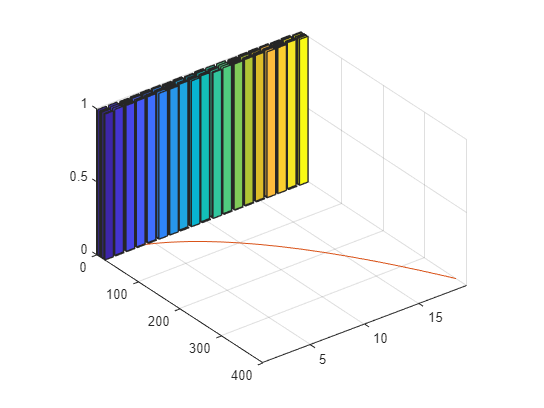

plot(x,z)
hold off

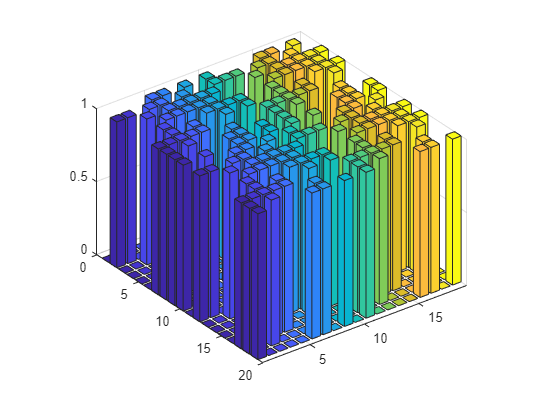

bar3(Z)

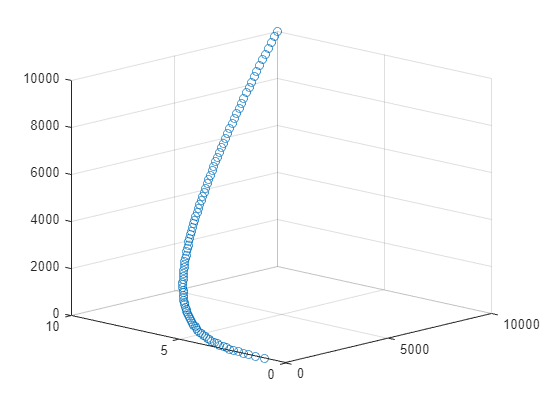

scatter3(z,y,z,'o')

## Funcions basiques

m = max(Z) % maxim per columnes

m =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


s = sum(sum(Z)) % suma de tots els elements

s = 170

## Funcions propies

c = myfunction(x)

c = 338350